Laboratorium 1

Przypomnienie podstaw środowiska Matlab oraz podstaw przetwarzania sygnałów.

Zad 1

Rozwiąż układ równań

x+2y+3z=1

4x+5,5y+6z=1

7x+8y+9,5z=1

syms x y z;

eqn1 = x + 2*y + 3*z == 1;
eqn2 = 4*x + 5.5*y + 6*z == 1;
eqn3 = 7*x + 8*y + 9.5*z == 1;

[A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [x, y, z]);
X = linsolve(A, B);
X

$$X = \left(\begin{array}{c} -\frac{19}{29}\\ \frac{6}{29}\\ \frac{12}{29} \end{array}\right)$$

Zad 2

Sporządź wykres okręgu (równania parametryczne) dla t=[0;1)

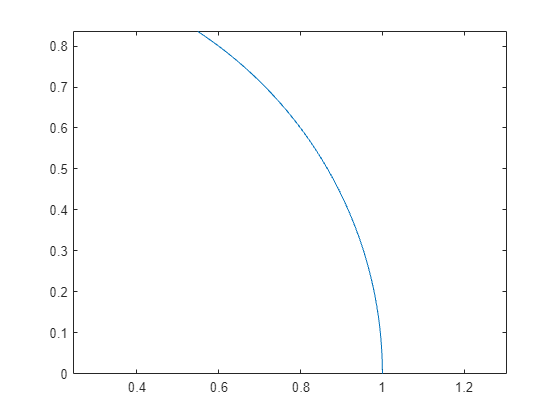

t = 0:0.01:1-0.01;
x = cos(t);
y = sin(t);


plot(x,y)
axis equal

Zad 3

Wygeneruj i przedstaw graficznie 3 okresy sygnałów. Amplituda A=+/- 1V, dla każdego wyznaczyć składową stałą i moc.

- Przebieg harmoniczny o częstotliwości f=1kHz

- Przebieg prostokątny o częstotliwości f=1kHz, wypełnieniu k=1/2 

- Przebieg piłokształtny o częstotliwości f=1kHz

- Przebieg trójkątny o częstotliwości f=1kHz

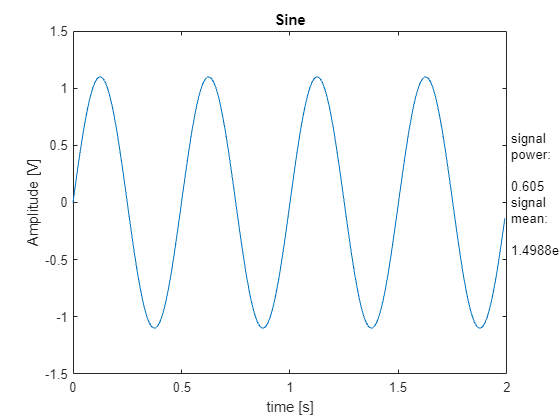

A = 1.1;
f =2;
k = 0.8;

w = 2*pi*f;
tmin = 0;
tmax = 2;
dt = 0.01;
t = tmin:dt:tmax-dt; %s

ad1 = A*sin(w*t);
power_ad1 = rms(ad1)^2;
mean_ad1 = mean(ad1);

plot(t, ad1);
title('Sine')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad1), 'signal mean: ', string(mean_ad1)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

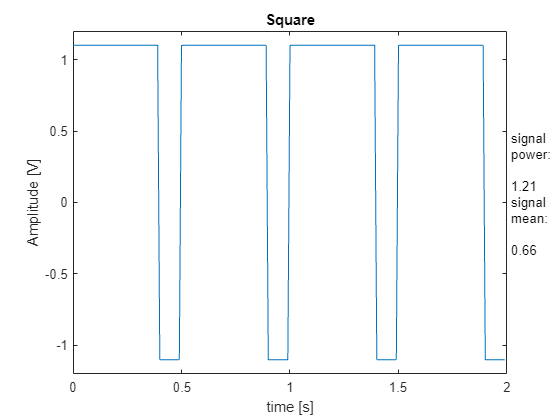

first_half = ones(1, round(1/(f*dt)*k)); second_half =  -1 * ones(1, round((1/(f*dt))*(1-k)));
ad2 = A * [first_half second_half];
for i = 0:(1/f)+1
    ad2 = cat(2,ad2,ad2);
end
power_ad2 = rms(ad2)^2;
mean_ad2 = mean(ad2);

plot(t, ad2)
ylim([-A-.1, A+0.1])
title('Square')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad2), 'signal mean: ', string(mean_ad2)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

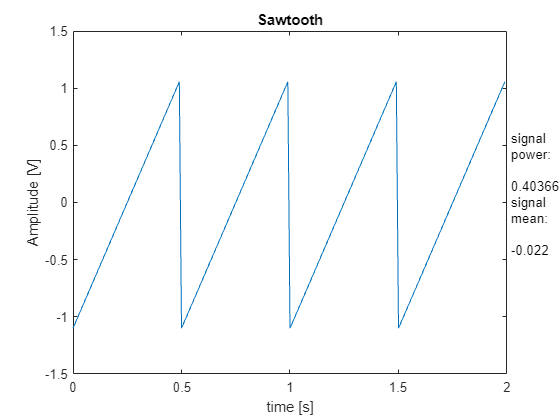

ad3 = A * sawtooth(w*t);
power_ad3 = rms(ad3)^2;
mean_ad3 = mean(ad3);

plot(t, ad3)
title('Sawtooth')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad3), 'signal mean: ', string(mean_ad3)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

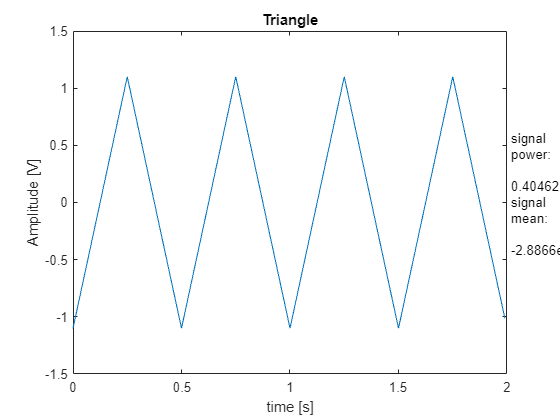


ad4 = A * sawtooth(w*t, .5);
power_ad4 = rms(ad4)^2;
mean_ad4 = mean(ad4);

plot(t, ad4)
title('Triangle')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad4), 'signal mean: ', string(mean_ad4)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

***Zad 1***

***Zbudować przebieg „prostokątny” o częstotliwości f=30Hz za pomocą funkcji sinusoidalnych***

- Trzech

- Pięciu

- Dziesięciu

- Stu

- Analiza przypadku (1): sygnał cyfrowy ma częstotliwość 1 MHz (2 Mbit/s), jest reprezentowany odpowiednio przez 1 i 3 oraz 1 i 3 i 5 harmoniczną, szerokość pasma, reprezentacja sygnału.

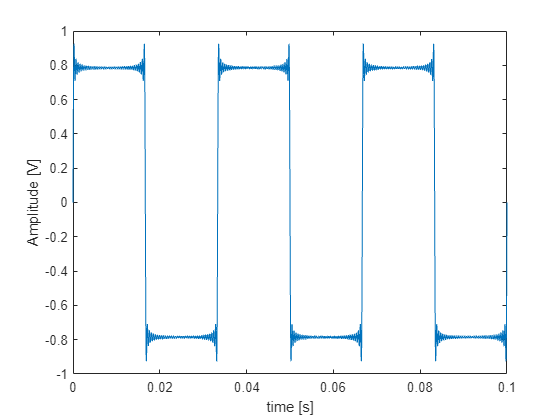

N_sines = 36;

t = 0:0.00001:3/30;
combined_sines = zeros(size(t));

for i = 1:2:N_sines*2
    combined_sines = combined_sines + (1/i) * sin(2*pi*30*i*t);
end



plot(t, combined_sines)
ylabel('Amplitude [V]')
xlabel('time [s]')

Zad 2

***Dla sygnału analogowego:***

- Dobierz  częstotliwość próbkowania fs sygnału f(t). Zaproponuj czas obserwacji - konsekwencje. Wyznacz DFT sygnału (wskazy). 

- Zmieniając liczbę bitów przetwornika AC (np. bit = 1, 3, 4, 8, 10), zbadać: jak zmienia się obraz próbkowanego sygnału, poziom (rząd wielkości) błędów kwantyzacji, porównać maksymalny błąd kwantyzacji z połową przedziału kwantowania, jakie zniekształcenia się pojawiają (wyższe harmoniczne sygnału), dla bit=1, 2, 4, 8 wyznacz współczynnik zawartości harmonicznych. Określ odstęp i szum kwantyzacji.

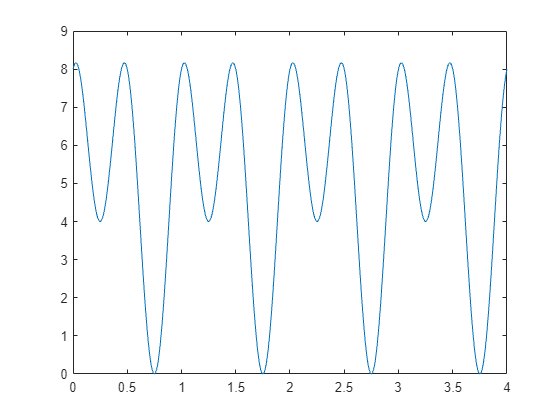

observation_time = 4; %observation time [seconds]
fs = 100; % sampling frequency [Hz]
T = 1/fs; %sampling period
n = 0:observation_time/T; %number of samples in observation time
t = n*T;

signal = 5 + 2*cos(2*pi*t-pi/2) + 3*cos(4*pi*t);

signal_fft = fft(signal);
frequency_vector = (fs/length(n))*(0:length(n)-1);
frequency_vector = (fs/length(n))*(-length(n)/2:(length(n)/2)-1);



plot(t, signal)

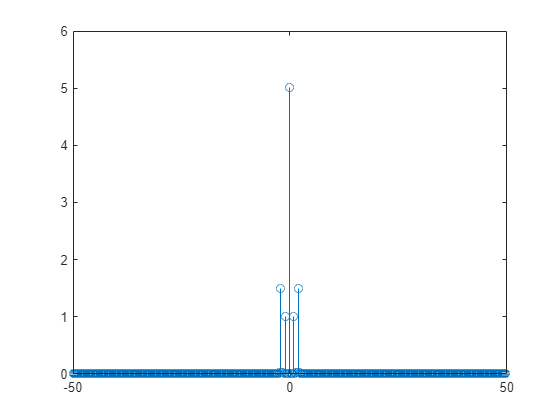

stem(frequency_vector, abs(fftshift(signal_fft))/length(n))
%xticks(frequency_vector)
xlim([-fs/2, fs/2])